# Computation of the free-decay response from ambient vibrations

## Summary

The random vibrations of a SDOF is computed using the central difference method, and a white noise is used as an input force. The free-decay response, obtained from random vibrations of a SDOF, is computed by using the Natural Excitation Technique (NeXT) and the Random Decrement Technique (RDT).  The free-decay response is used to estimate the modal damping ratio of the system. The natural-frequency is obtained by pick-picking method. Note: since a SDOF is here used, there is no point in calculating the mode shape.

## Initialisation

clearvars;close all;clc;
rng(10) % used for the sake of reproducibility only

### Structural parameters

w0 = 2*pi*0.2; % eigen-frequency (rad/s) -> 0.2 Hz is the natural frequency
eta = 0.01; % damping ratio
wd = w0.*sqrt(1-eta.^2); % damped eigen frequency (rad/s)
M = 1; % mass
K = w0^2.*M; % stifness
C = 2*eta.*M.*w0; % damping


### Time parameter

N = 3000; % number of time step
t = linspace(0,1800,N); % time
dt = median(diff(t)); % time step
fs = 1/dt;


### Definition of the random force 

% A Gaussian white noise is used as an input
F0 = 0.1; % amplitude of force
F = F0.*randn(1,N); 

### initial conditions

v0 = 0; % no initial speed
x0 = F0/K; %initial displacement

## Response computation

% output response
y = CentDiff(F,M,K,C,dt,x0,v0);


### Data visualization

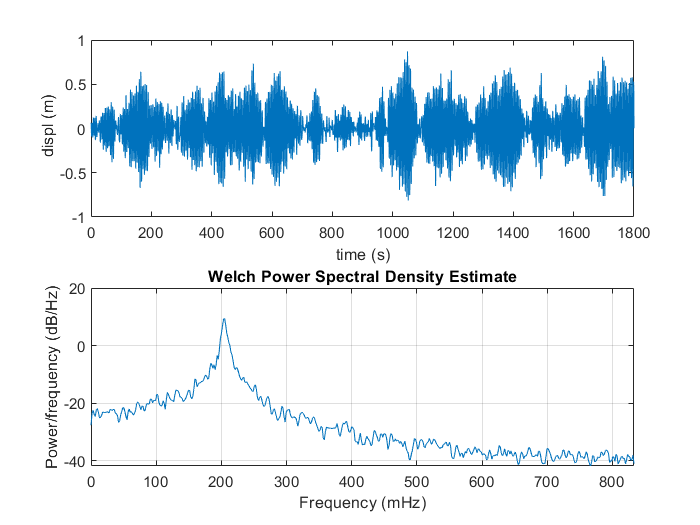

clf;close all;
figure
subplot(211)
plot(t,y)
xlabel('time (s)')
ylabel(' displ (m)')
subplot(212)
pwelch(y,[],[],[],1/dt)
set(gcf,'color','w')

## Application of the Random Decrement Technique (RDT)

Trick: I artifically increase the sampling frequency of the recorded data to improve the accuracy of the triggering value for the RDT method. To increase the sampling frequency, I am using the function interp(). It's quick and dirty.

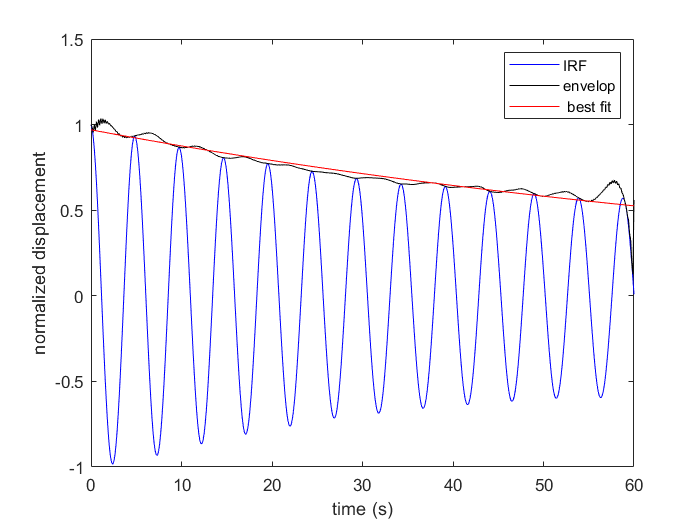

coeff = 5; % interpolation coefficient
newDT = median(diff(interp(t,coeff)));
newY = interp(y,coeff);

% triggering value
ys = max(abs(y))/5;
% subsegment duration
Ts = round(t(end)/30);

% RDT function
[IRF,newT] = RDT(newY,ys,Ts,newDT);

% get the envelop of the curve with the hilbert transform:
envelop = abs(hilbert(IRF));
envelop(1)=IRF(1);

clf;close all;
figure
hold on; box on;
plot(newT,IRF,'b',newT,envelop,'k');
xlabel('time (s)')
ylabel('normalized displacement')
xlim([0,Ts])
set(gcf,'color','w')

% fit an exponential decay to the envelop
optionPlot = 1;
wn = 2*pi*0.2; % -> obtained with peak picking method (fast way)
[zeta] = expoFit(envelop,newT,wn,optionPlot);
legend('IRF','envelop',' best fit')




fprintf([' The target modal damping ratio is ',num2str(eta),' \n'])

 The target modal damping ratio is 0.01 


fprintf([' The calculated modal damping ratio is ',num2str(zeta,2),' \n'])

 The calculated modal damping ratio is 0.0081 


## Application of the natural Excitation Technique (NeXT) - method 1

Trick: I artifically increase the sampling frequency of the recorded data to improve the accuracy of the triggering value for the RDT method. To increase the sampling frequency, I am using the function interp(). It's quick and dirty. Using interp1 with a new time vector may be a better idea.

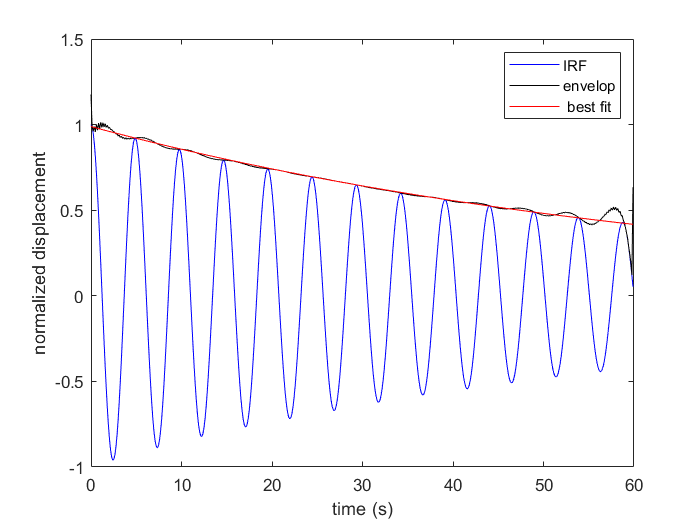

Ts = 60; % We want segments of 60 seconds
method = 1; % cross-covariance calculated with ifft

coeff = 5; % interpolation coefficient
newDT = median(diff(interp(t,coeff)));
newY = interp(y,coeff);
[IRF,newT] = NExT(newY,newDT,Ts,method);

% get the envelop of the curve with the hilbert transform:
envelop = abs(hilbert(IRF));
% envelop(1)=IRF(1);

clf;close all;
figure
hold on; box on;
plot(newT,IRF,'b',newT,envelop,'k');
xlabel('time (s)')
ylabel('normalized displacement')

set(gcf,'color','w')

% fit an exponential decay to the envelop
optionPlot = 1;
wn = 2*pi*0.2; % -> obtained with peak picking method (fast way)
[zeta] = expoFit(envelop,newT,wn,optionPlot);
legend('IRF','envelop',' best fit')
xlim([0,Ts])


fprintf([' The target modal damping ratio is ',num2str(eta),' \n'])

 The target modal damping ratio is 0.01 


fprintf([' The calculated modal damping ratio is ',num2str(zeta,3),' \n'])

 The calculated modal damping ratio is 0.0115 


## Application of the natural Excitation Technique (NeXT) - method 2

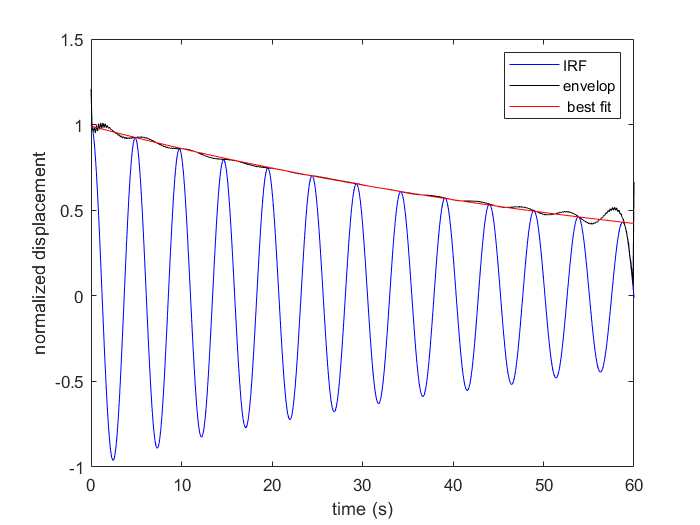

Ts = 60; % We want segments of 60 seconds
method = 2; % cross-covariance calculated xcov

coeff = 5; % interpolation coefficient
newDT = median(diff(interp(t,coeff)));
newY = interp(y,coeff);
[IRF,newT] = NExT(newY,newDT,Ts,method);

% get the envelop of the curve with the hilbert transform:
envelop = abs(hilbert(IRF));
% envelop(1)=IRF(1);

clf;close all;
figure
hold on; box on;
plot(newT,IRF,'b',newT,envelop,'k');
xlabel('time (s)')
ylabel('normalized displacement')

set(gcf,'color','w')

% fit an exponential decay to the envelop
optionPlot = 1;
wn = 2*pi*0.2; % -> obtained with peak picking method (fast way)
[zeta] = expoFit(envelop,newT,wn,optionPlot);
legend('IRF','envelop',' best fit')
xlim([0,Ts])


fprintf([' The target modal damping ratio is ',num2str(eta),' \n'])

 The target modal damping ratio is 0.01 


fprintf([' The calculated modal damping ratio is ',num2str(zeta,3),' \n'])

 The calculated modal damping ratio is 0.0113 
